# Exercise 3: Quadratic Programming

Finn Vehlhaber and Leonardo Pedroso

**Run the sections one by one by clicking into the respective code window and hitting "Run Section". Sentences highlighted in bold give instructions on how to complete the given code. Code lines like this need to be completed by you:**

% ----- complete code here
% (incomplete code here)
% -----

Clean up script

clear; close all; clc

### Exercise 3: Quadratic Programming

Consider Exercise 3 in the handout. 

**Complete the variables, constraints, and objective in the code given below**

yalmip('clear');

% optimization variables
% ----- complete code here
x1 = sdpvar(1,1);
x2 = sdpvar(1,1);
% -----

% Define constraints
% ----- complete code here
constraints = [x1 + 2*x2 <= 10;
    7*x1 - x2 <= 15;
    x1 >= 0;
    x2 >= 0]

+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                    Constraint|   Coefficient range|
+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality 1x1|             1 to 10|
|   #2|   Element-wise inequality 1x1|             1 to 15|
|   #3|   Element-wise inequality 1x1|              1 to 1|
|   #4|   Element-wise inequality 1x1|              1 to 1|
+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++


% -----

% Define objective
% ----- complete code here
objective = (x1-4)^2+(x2-4)^2;
% -----

% Solve problem
opts = sdpsettings('solver','quadprog','verbose',2);
optimize(constraints,objective,opts);

MOSEK Version 10.1.26 (Build date: 2024-2-21 13:35:17)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Windows/64-X86

Problem
  Name                   :                 
  Objective sense        : minimize        
  Type                   : QO (quadratic optimization problem)
  Constraints            : 4               
  Affine conic cons.     : 0               
  Disjunctive cons.      : 0               
  Cones                  : 0               
  Scalar variables       : 2               
  Matrix variables       : 0               
  Integer variables      : 0               

Optimizer started.
Quadratic to conic reformulation started.
Quadratic to conic reformulation terminated. Time: 0.00    
Optimizer terminated. Time: 0.00    


Interior-point solution summary
  Problem status  : PRIMAL_AND_DUAL_FEASIBLE
  Solution status : OPTIMAL
  Primal.  obj: -3.0111111081e+01   nrm: 1e+01    Viol.  con: 2e-08    var: 0e+00  
  Dual.    obj: -3.0111111065e+01   nrm: 5e-01    Viol

[value(x1);value(x2)]

ans =     2.6667
    3.6667


Plot

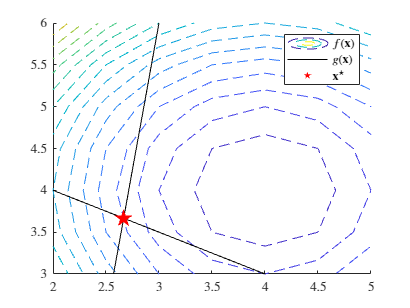

x1vector = 0:.5:10;
x2vector = 0:.5:10;
figure;
hold on
% objective function
contour(x1vector,x2vector,(x1vector - 4).^2'*ones(1,21) + ones(21,1) * (x2vector - 4).^2,0:0.5:10,'--','DisplayName','$f(\mathbf{x})$')
% constraints
plot(x1vector,5-x1vector/2,'k','DisplayName','$g(\mathbf{x})$');
plot(x1vector,7*x1vector-15,'k','HandleVisibility','off');
scatter(value(x1),value(x2),200,'r','filled','pentagram','DisplayName','$\mathbf{x}^\star$')
hold off
xlim([2 5])
ylim([3 6])
legend('Interpreter','latex','Location','northeast')
set(gca,'ticklabelinterpreter','latex')